# Excersise 3

Here the objective is to move the end-effector of a painting robot tangent to a plane with a particular painting (curve on it). The end effector must keep the same orientation w.r.t the canvas and follow the trajectory.

import plotFrame.*;

clear all;

alpha = pi/6; % degrees

plane_ang = pi/18;

points_ang = plane_ang - alpha;

points = 10*[0 .82 .92 0 0 -.92 -.82 0; .66 .9 0 ...
-.83 -.83 0 .9 .66];

[curve, t] = fnplt(cscvn(points));

% plot(curve(1, :), curve(2, :));
% axis equal;

curve3D = [curve; zeros(1, length(curve))];
rotCurve3D = rotx(rad2deg(plane_ang))*curve3D;

Ts = zeros(4, 4, length(rotCurve3D));

for i=1:length(rotCurve3D)
    Ts(1:3, 1:3, i) = rotx(rad2deg(points_ang));
    Ts(:, 4, i) = [rotCurve3D(:, i); 1];
end

Hrot = [rotx(rad2deg(alpha)) zeros(3, 1);
        zeros(1, 3) 1
       ];

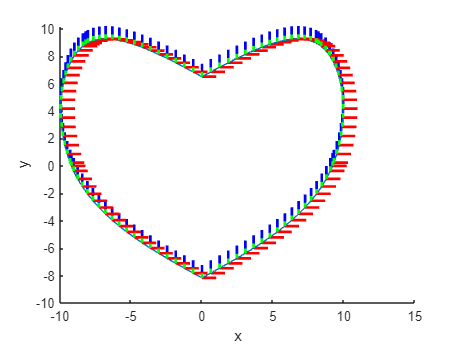

hold on;

plot3(rotCurve3D(1, :), rotCurve3D(2, :), rotCurve3D(3, :));


for i=1:length(rotCurve3D)
    plotFrame(Ts(:, :, i));
end

xlabel("x");
ylabel("y");
zlabel("z");

% hold off;

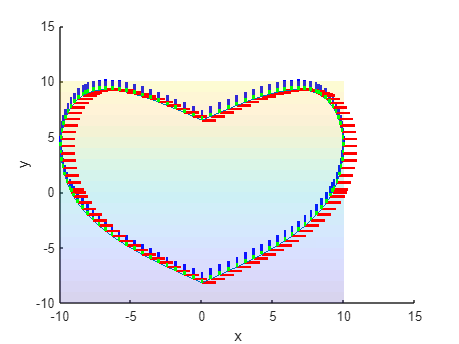

[x, y] = meshgrid(-10:1:10);

coeff = getPlaneCoff(rotCurve3D);
z = coeff(1).*x + coeff(2).*y + coeff(4);

surf(x,y,z,'FaceAlpha',0.2, 'EdgeColor','none');

function coeff=getPlaneCoff(curve)
    non_collinear_points_idxs = randi(length(curve), 3);
    non_collinear_points = curve(:, non_collinear_points_idxs);

    A = non_collinear_points(:, 2) - non_collinear_points(:, 1);
    B = non_collinear_points(:, 3) - non_collinear_points(:, 1);

    normal = cross(A, B);
    normal = -normal ./ normal(3);
    
    k = -normal'*non_collinear_points(:, 1);
    coeff = [normal; k];
end